##  МИУ

close all;
clear variables;

Входные параметры

%  1 - входные данные 
k0 = 2*pi;
% Параметры среды-1
e1 = 2.56;
mu1 = 1;
k1 = k0*sqrt(mu1*e1);
eta1 = 120*pi*sqrt(mu1/e1);

% Параметры среды-2
k2 = k0;
eta2 = 120*pi;

% Параметры программы
N = 1200; % количество точек на круга

phi_i_grad = 0; % угол падения [град]
phi_i_rad = deg2rad(phi_i_grad); % угол падения [рад]
gamma = 1.781072417990;

% ОСНОВНОЙ ЭЛИПС
a = 2; 
b = 1;

% ВСПОМОГАТЕЛЬНЫЕ ЭЛИПСЫ
f = sqrt(a^2 - b^2);

a2 = 1.8;  % внутрений
b2 = sqrt(a2^2 - f^2); 

a1 = 2.2; % внешений
b1 = sqrt(a1^2 - f^2); 

% ТЕСТОЫЙ КРУГ
% a = 5/(2*pi);
% b = a;
% a1 = a + 0.1;
% b1 = a1;
% a2 = a - 0.1;
% b2 = a2;

% ========================================================================
%  Построение круга
dphi_grad = 360/N; % угловой шаг на круга [град]
dphi_rad =  deg2rad(dphi_grad); % угловой шаг на круга [рад]

Генерация точек контура для ВИ и основного

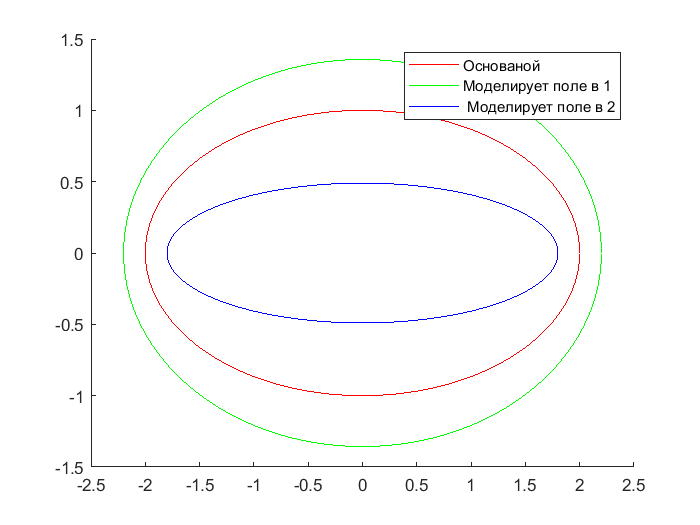

x = zeros(1,N);
z = zeros(1,N);

for i = 1 : N
    cur_phi_grad = (i-1)*dphi_grad + dphi_grad/2;
    
    % основной элипс
    x(i) = a*cosd(cur_phi_grad);
    z(i) = b*sind(cur_phi_grad);

    % вспомогательные элипсы
    xAS1(i) = a1*cosd(cur_phi_grad);
    zAS1(i) = b1*sind(cur_phi_grad);
    xAS2(i) = a2*cosd(cur_phi_grad);
    zAS2(i) = b2*sind(cur_phi_grad);
end

figure;
hold on;
plot(x, z, 'r')
plot(xAS1, zAS1, 'g')
plot(xAS2, zAS2, 'b')
hold off
legend('Основаной','Моделирует поле в 1',' Моделирует поле в 2')

% Генерация касательных
for i = 1 : N
    tx(i) = -a^2*z(i)/sqrt(a^4*z(i)^2+b^4*x(i)^2);
    tz(i) =  b^2*x(i)/sqrt(a^4*z(i)^2+b^4*x(i)^2);
end

Посчитаем нормуль для каждого отрезка

nx = zeros(1,N);
nz = zeros(1,N);

for i = 1 : N
    cur_phi_grad = (i-1)*dphi_grad + dphi_grad/2;
    nx(i) = cosd(cur_phi_grad);
    nz(i) = sind(cur_phi_grad);
end

Посчитаем t для каждого отрезка

%  Посчитаем n для каждого отрезка
%  нормальный вектор найдем с помощью матрицы повороты
    alpha = 90;
    matrix = [cosd(alpha),-sind(alpha); sind(alpha),cosd(alpha)];

for i = 1 : N
     matrix_temp = [nx(i), nz(i)]*matrix;
     tx(i) = matrix_temp(1);
     tz(i) = matrix_temp(2);
end

% ========================================================================
% 3 - cам ходя расчета 
% списик для хранения элементов системы 
Z = zeros(2*N,2*N);
    
for m  = 1 : N
    xm = x(m);
    zm = z(m);
    txm = tx(m);
    tzm = tz(m);
    
    for n = 1 : N
        % контур 1
        xn1 = xAS1(n);
        zn1 = zAS1(n);
        
        % контур 2
        xn2 = xAS2(n);
        zn2 = zAS2(n);
   
        % Растояние между m и n
        xmn1 = (xm - xn1);
        zmn1 = (zm - zn1);
        r1 = sqrt(xmn1^2 + zmn1^2);
        
        % Растояние между m и n        
        xmn2 = (xm - xn2);
        zmn2 = (zm - zn2);
        r2 = sqrt(xmn2^2 + zmn2^2);
        
        E1y = besselh(0,1,k1*r1);
        H1x = - 1i/eta1 * zmn1/r1 * besselh(1,1,k1*r1);
        H1z = + 1i/eta1 * xmn1/r1 * besselh(1,1,k1*r1);
        
        E2y = besselh(0,1,k2*r2);
        H2x = - 1i/eta2 * zmn2/r2 * besselh(1,1,k2*r2);
        H2z = + 1i/eta2 * xmn2/r2 * besselh(1,1,k2*r2);
        
        % элементы системы       
        E1mn = E1y;
        E2mn = -E2y;
        
        H1mn = txm*H1x + tzm*H1z;
        H2mn = -(txm*H2x + tzm*H2z);
        
        % запись в массив для дальнешего решения 
        Z(m,n) = E1mn;
        Z(m,n+N) = E2mn;
        Z(m+N,n) = H1mn;
        Z(m+N,n+N) = H2mn;
    end
end
% 

E = zeros(2*N,1);
% падающее поле 
for m = 1 : N
    xm = x(m);
    zm = z(m);
    txm = tx(m);
    tzm = tz(m);

    % cоставляющие полей
    cx = -1i*k2*cosd(phi_i_grad);
    cz = -1i*k2*sind(phi_i_grad);
    
    Eiy = exp(cx*xm+cz*zm);
    Hix = 1/eta2*sind(phi_i_grad) * Eiy;
    Hiz = -1/eta2*cosd(phi_i_grad) * Eiy;
    
    % элементы системы  
    Ei = Eiy;
    Hi = txm*Hix + tzm*Hiz;

    % запись в массив для дальнешего решения 
    E(m) = Ei;
    E(m+N) = Hi;
end    


% Расчитаем токи
% тут зашито сразу 2 тока
I = Z\E;


% отделим один ток от другого
j1 = I(1:N);
j2 = I(N+1:2*N);

Сделаем счетчик для графика в градусах

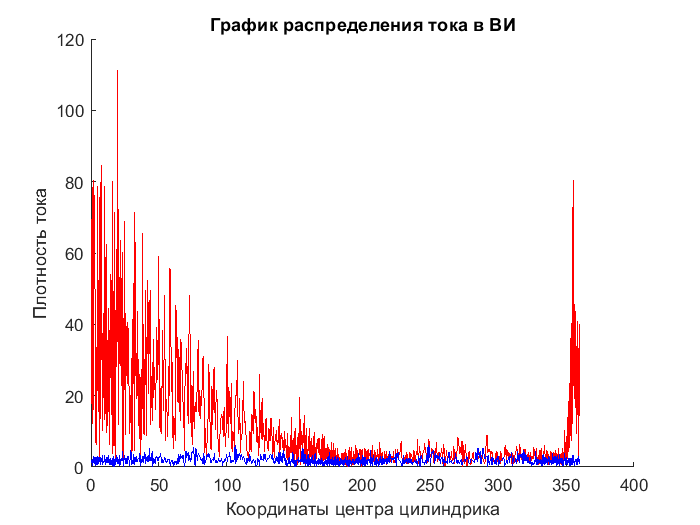

for i = 1 : N
    z_m = z(i);
    x_m = x(i);
    
    if (x_m <= 0 && z_m < 0) || (x_m >= 0 && z_m < 0)
        phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi+360;
    else
        phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi;
    end
end

figure;
hold on;
plot(phi_for_graf_real, abs(j1), 'r');
plot(phi_for_graf_real, abs(j2), 'b');
title('График распределения тока в ВИ'); 
xlabel('Координаты центра цилиндрика'); 
ylabel('Плотность тока');
hold off;

Полярные графики

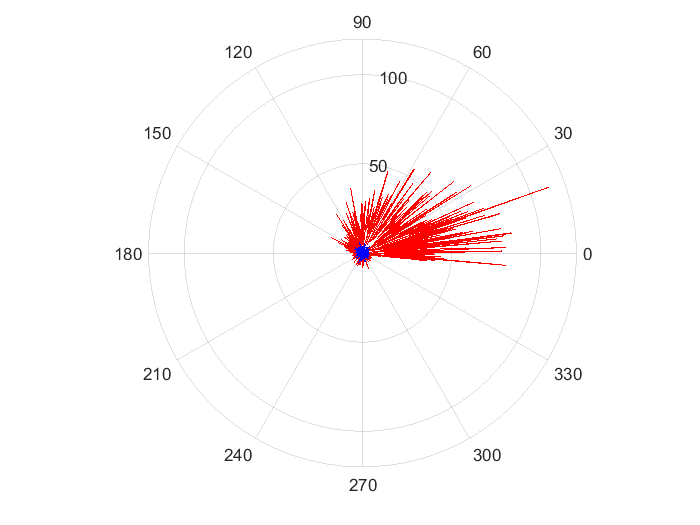

% полярный графки токов
polarplot(deg2rad(phi_for_graf_real), abs(j1), 'r',deg2rad(phi_for_graf_real), abs(j2), 'b');

### Электрическое Поле на поврехности 

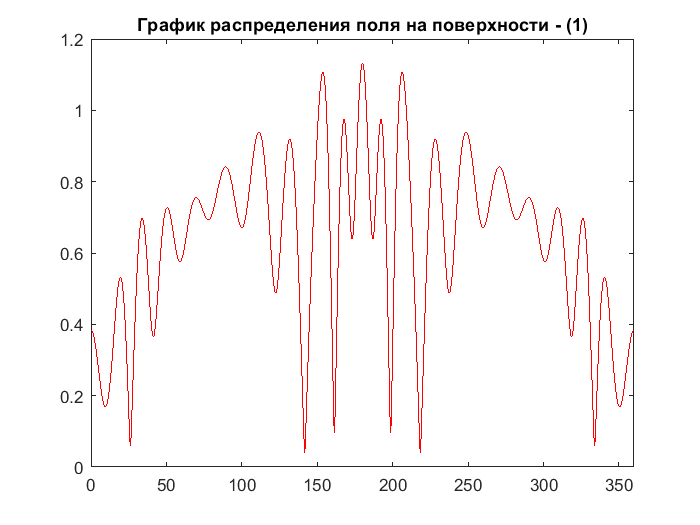

E_surf = zeros(N, 1); 
for m  = 1 : N
    xm = x(m);
    zm = z(m);
    n_for_graf(m) = m; % для графика 
    
    
    E_surf_n = 0;
    for n = 1 : N
        xn2 = xAS2(n);
        zn2 = zAS2(n);
        
        % Растояние между m и n
        xmn2 = xm - xn2;
        zmn2 = zm - zn2;
        r2 = sqrt(xmn2^2 + zmn2^2);
        
        E_surf_n = E_surf_n + j2(n) * besselh(0,1,k2*r2);
    end
    
    E_surf(m) =  E_surf_n; 
 end
 
 
figure;
plot(phi_for_graf_real, abs(E_surf), 'r');
title('График распределения поля на поверхности - (1)'); 
xlim([0 360])

## ЭПР


RCS = zeros(1, 721);
for p = 1 : 721
    Sum_E = 0;
    phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    phi_for_graf_DA(p) = (p-1)/2; % угол для графика
    
    cx = - 1i*k2*cosd(phi);
    cz = - 1i*k2*sind(phi);
    

        for n = 1 : N
            txn = tx(n);
            tzn = tz(n);
            xn = xAS2(n);
            zn = zAS2(n);
            
            Sum_E = Sum_E + j2(n)*exp(cx*xn+cz*zn);      
        end
    
    RCS(p) = 10*log10((4/k2)*Sum_E*conj(Sum_E));

end

% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_for_graf_DA, RCS,'r-');

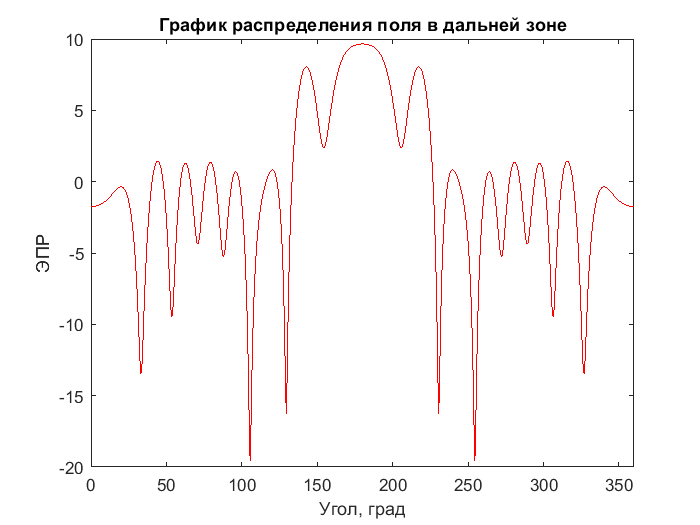

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

### Вывод данных для графиков

name_file = strcat('Esurf_MAS_elips_diel_Epol_j2_', num2str(N),'.dat');
f01 = fopen(name_file,'w');

% за максимум Y примем значения в центре передней стороны падения

for n= 1 : N
    fprintf(f01,' %10.5f %10.5f\n', phi_for_graf_real(n), abs(E_surf(n)));
end

fclose(f01);

name_file = strcat('DA_MAS_elips_diel_Epol_j2_', num2str(N),'.dat');
f03 = fopen(name_file,'w');

% за максимум Y примем значения в центре передней стороны падения

for n= 1 : 721
    fprintf(f03,' %10.5f %10.5f\n', phi_for_graf_DA(n), RCS(n));
end

fclose(f03);

% function [H_calc] = H(n,x)
%     H_calc = besselh(n,1,x); 
% end
% 
% function [J_calc] = J(n,x)
%     J_calc = besselJ(n,x); 
% end
%     
% function [dJ_calc] = dJ(n,x)
%     dJ_calc = n/x*besselj(n,x) - besselj(n+1,x);
% end
% 
% function [dH_calc] = dH(n,x)
%     dH_calc = n/x*besselh(n,1,x) - besselh(n+1,1,x);
% end